## Power and Torque Requirements

Performance analysis

Assumptions

- Coaxial

- No tail rotor


$$P_{\textrm{total}} =\kappa_{\textrm{trans}} \left\lbrack \left(\kappa +\kappa_{\int } \right)\;{\;P}_{i_{\textrm{MR}} } +P_{0_{\textrm{MR}} } +P_p +P_{0_{\textrm{TR}} } +P_{\textrm{AUX}} \right\rbrack$$


Sanity check

main rotor torque proportional to W^(2/3)

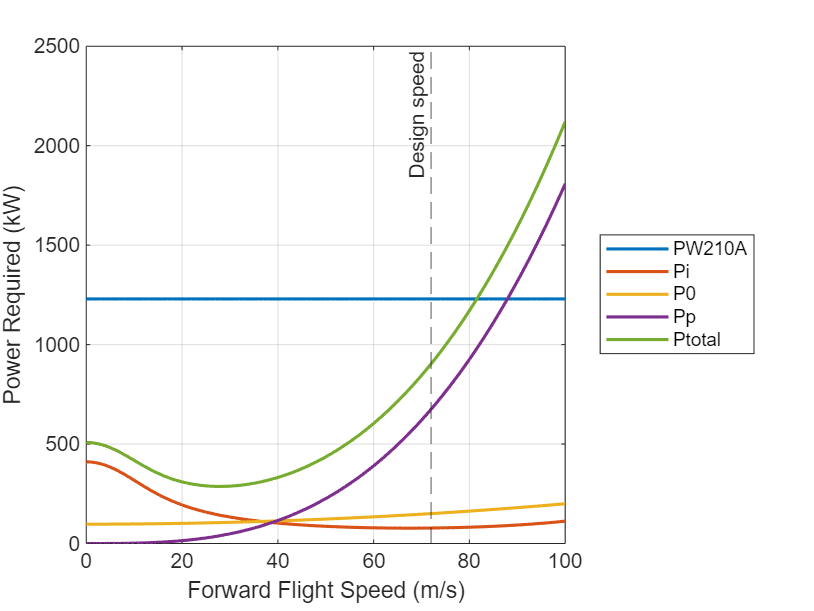

clear
clc

V=[0:1:100];%forward flight speed m/s Design point is 72m/s

%parameters CHECK THESE VALUES!
rho=1.058;
Nb=3;
c=0.2573;
R=10.29/2;
Vtip=210;
Cd0=0.01;
Sref=2.866; %some reference area
Cdf=0.1;%drag coefficient of fuselage
f=3.4177; %roughly 0.9-5m^2
khover=1.15;%roughly 1.1-1.15
kint= 1.1412;%for coaxial it is 1.219
W=3351.75*9.81; %3000-4000

K=4.65; %good estimate for mu<0.5
mu=V/Vtip;
A=pi*R^2;
T=W/2;
CT=T/(rho*A*Vtip^2);

%using linear inflow model 
lam2   = (-mu.^2 + sqrt(mu.^4 + CT.^2))/2;   % λ_i^2 from quadratic
lambdai= sqrt(lam2);
lambdah=sqrt(CT/2);
lambdai=lambdah*sqrt( sqrt(0.25.*(mu./lambdah).^4 +1    )-0.5.*(mu./lambdah).^2   );

Pengine=614.9*2; %engine power kW
P0=2*(1/8)*rho*Nb*c*R*(Vtip^3)*Cd0*(1+K*mu.^2)/1000; %divided by 1000 for kW
Pp=0.5*rho*(V.^3)*f/1000;
kfactor=khover*kint*cosh(7.5*mu.^2);
alpha=10*pi/180;
Pi=kfactor*(2*T*cos(alpha)).*lambdai*Vtip/1000;
Ptotal=Pi+P0+Pp;

figure %airspeed vs Power plot
plot(V, Pengine*ones(size(V)), 'LineWidth', 1.5);   % horizontal line
hold on
plot(V,Pi, 'LineWidth', 1.5) %Pi
plot(V,P0, 'LineWidth', 1.5) %P0
plot(V,Pp, 'LineWidth', 1.5) %Pp
plot(V,Ptotal, 'LineWidth', 1.5) %Ptotal
xline(72, '--', 'Design speed', 'LabelHorizontalAlignment','left');
legend('PW210A', 'Pi', 'P0', 'Pp', 'Ptotal', 'Location','eastoutside')
ylabel('Power Required (kW)')
xlabel('Forward Flight Speed (m/s)')
%ylim([0 1500])
grid on


excesspower=Pengine-Ptotal;
%compute excess power!
%compute max rate of climb
%compute speed for minimum power
%speed for max range